# Neural Networks Part 2

## Running the neural network for the ovarian cancer data set

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. Each iteraction where we run a single round of forward and backward propagation is called an **epoch. **This is another hyperparameter that we can tune to assess model performance. 

The `SNN` function for the shallow neural network is modularized to the three steps we performed: forward propagation, evaluating the cost, and back propagation. The docstring is provided below:

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

clear all; 
rng(2);

% 1. Split the dataset into a training and testing set using the accessory
% function.
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

% 2. Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 2;
hyperparameters.alpha            = 0.05;
hyperparameters.epoch            = 500;
hyperparameters.actFnc           = 'Sigmoid';
hyperparameters.randomstate      = 2;

% 3. Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters);

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

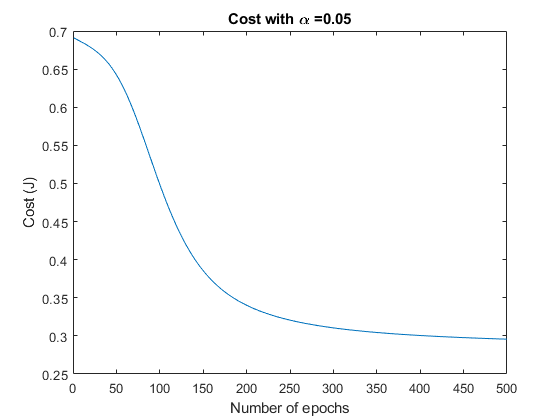

figure
plot(1:length(model.J), model.J);
title(strcat('Cost with \alpha = ', string(hyperparameters.alpha)));
xlabel('Number of epochs');
ylabel('Cost (J)');

Given the set of parameters and hyperparameters we fed into the trained model, a minimum cost value approaches 0.28 when the learning rate is 0.05 under 500 epochs.

### Assessing model accuracy

#### Hold out

Next, let's use the test set to come up with a prediction. To do that using our neural network, we can use the `predict `function, which takes the test data and outputs predictions for classification. The docstring is provided below:

ypred = predict(model, Xtest, Ytest, 'SNN');

Now that we have a prediction from our neural network, we can evaluate the model accuracy. Note that the values from `yred` are not necessarily 0 and 1. To transform our values back to our labels, we need to determine a decision boundary for classification. Let's use mean value of $y_{\textrm{pred}}$ as the decision boundary, where observations with a value greater than the $\textrm{mean}\left(y_{\textrm{pred}} \right)$ are assigned to be 1 (malignant). Otherwise, we'll assign that value to be 0 (benign). 

We'll also plot the confusion matrix and report the hold out accuracy using the `plotConfusionMatrix` code in the directory.

Summary = plotConfusionMatrix(Ytest, ypred);
disp(strcat('Hold-out malignant classification accuracy: ', ...
    string(Summary.Class1)))
disp(strcat('Hold-out benign classification accuracy: ', ...
    string(Summary.Class2)))
disp(strcat('Hold-out average classification accuracy: ', ...
    string(Summary.Accuracy)))

#### k-fold cross validation

Of course, the hold out accuracy itself is not necessarily the best measure to evaluate the error from a machine learning model. Let's also run **k-fold cross validation** and obtain a relatively unbiased estimate of the test error. 

The `crossValidate` function is used to compute k-fold cross validation with two classes. 

kfold = 10;
type  = 'SNN';
trainingSize = 0.8;
randomState = 2;

% Run cross validation
Summary = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type);

% Plot confusion matrix
figure;
labels = {'Malignant', 'Benign'};
confusionchart(Summary.cm, labels, ...
    'Normalization', 'total-normalized');
title('Confusion matrix from 10-fold cross validation');
disp(strcat('10-fold CV malignant classification accuracy: ', ...
    string(Summary.Class1)))
disp(strcat('10-fold CV benign classification accuracy: ', ...
    string(Summary.Class2)))
disp(strcat('10-fold CV average classification accuracy: ', ...
    string(Summary.Accuracy)))

## Issues in training neural networks

While neural networks are really popular for artificial intelligence research and applications, [there are issues with training them](https://machinelearningmastery.com/why-training-a-neural-network-is-hard/). 

### Initializing values for w and b

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 2 alternative cases that are different from our random intiialization of small numbers: if w and b are all zeros and all ones.

#### Setting w and b to be all zeros

We'll go back to our synthetic dataset with 50 observations and 6 features and plot the results when w and b are all zero.

rng(2);

Xtrain = normrnd(0, 1, [50, 6]);

w = [0, 0, 0, 0, 0, 0];
b = zeros([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on;
plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
ylim([-0.1 0.6]);
xlabel('Observations');
ylabel('Z or sigmoid(Z)');

If the values are all zeros, the neural network stops learning the features - they will be stuck at Z = 0 and A = 0.5 during every iteration.

#### Setting w and b to be all ones

Let's see what happens when we set w and b to be all ones:

w = [1, 1, 1, 1, 1, 1];
b = ones([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on;
plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
xlabel('Observations');
ylabel('Z or sigmoid(Z)');

As you can see, our features (blue) end up being transformed to log-odds in the range [0, 1] (red) by the activation function. Thus, the neural network algorithm essentially becomes a logistic regression classifier when using the sigmoid activation function and the biases are all equal to 1.

#### Symmetry breaking

**Symmetry breaking** is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning and we allow the neural network to approach a better solution through back propagation / gradient descent.

### Overfitting

Recall that our objective in machine learning is to build a model that balances the model's ability to minimize bias and variance (the **bias-variance tradeoff**). Neural networks are relatively complex models and are susceptible to model overfitting. In other words, they are susceptible to learning from noisy data. This is especially true when the number of predictors `p` is much greater than the number of observations `n`. 

To address this issue, **regularization (ie Ridge or LASSO)** is usually imposed in the loss function and gradients. Recall that the regularized term is a function of the weights and a tuning factor $\lambda$. Regularization reduces overfitting by penalizing the weights. 

The following code imposes ridge regularization on the cross entropy loss function and subsequent back propagation for our shallow neural network:

Note that `lambda` is the ridge regularization term, and would be another hyperparameter we have to tune if we decide to regularize our neural network. 

### Data scaling

While neural networks can capture trends in complex / non-standardized datasets, there are several advantages to train using standardized data:

- We reduce the training time because we're examining a smaller range of values and thus reducing the time it takes for the weights to converge to an optimal value.

- We reduce the change of getting stuck in a local optima when computing the loss, due to chance.

Recall that there are two common ways to scale our data depending on how we wish to interpret each feature: the **Z-score method**, and the **min-max scaling method**. The z-score method will ensure that each value is scaled to have a mean of 0 and standard deviation of 1. 


$$X_{z-\textrm{score}} =\frac{X_{\textrm{ij}} -\textrm{mean}\left(X_j \right)}{\textrm{std}\left(X_j \right)}$$


While useful, scaling in this manner can produce results that don't necessarily reflect true values, especially if our feature is composed of only positive values. In those cases, min-max scaling can actually be better, where we scale the data point from a value of 0 to 1:


$$X_{\min -\max } =\frac{X_{\textrm{ij}} -\min \left(X_j \right)}{\max \left(X_j \right)-\min \left(X_j \right)}$$


### Multiple cost minima

The error function may not have a single minimum. In other words, there may be multiple minima that gradient descent can converge to. To try to get the best solution, scaling the dataset, changing the complexity of the model (ie adding more hidden layers), and exploring different learning rates can allow us to overcome this gradient problem.

### Determining the best number of activation nodes and hidden layers to use in a neural network framework

Recall that we've been using a naive approach to determining the number of activation nodes in our neural network, where we assumed two activation nodes are best because we're trying to split the data into two classes. While it's a good starting point, it's another assumption we're imposing on the model.

To determine the best number of activation nodes to use for either a single layer or `L` layers, we need to optimize this hyperparameter in a systematic way. **One way to do so is to run k-fold cross validation, and see which number of activation nodes best improves the accuracy / minimzes the error from the model. **

This same method can also be used to determine the number of hidden layers used in the model. However, as we change the number of hidden layers in the model, we also change the optimal number of activation nodes. We'll discuss how to tune these hyperparameters in the last part of the lecture.

## Benchmarking against a logistic regression classifier

A neural network is a more flexible model compared to other models, in that it performs both linear and nonlinear transformations on the data. Let's see how well our shallow neural network performs against a logistic regression classifier, a less flexible model that only performs nonlinear transformations on the dataset.  

### Logistic regression

Recall that the formulation for a logistic regression problem is 1) applying the sigmoid function to our linear equation $\hat{f} \left(x\right)=X^T \beta$ to transform the values to log-odds, then 2) estimating $\beta$ from the data $X$ such that it maximizes the likelihood of estimating  a value $\hat{y}$ close to the true value of $y$.

Thus the equation we're trying to solve for a logistic regression problem is formulated below:


$$\hat{f} \left(x\right)=\frac{1}{1+e^{-X^T \beta } }$$


We'll be using the `mnrfit` function to get our $\beta$ coefficients, then run 10-fold cross validation. 

clear all;
rng(2);

kfold = 10;
type = 'Logistic';
trainingSize = 0.8;
randomState = 2;
logisticCM = crossValidate(trainingSize, randomState, ...
                            [], kfold, type);
% Plot confusion matrix
figure;
labels = {'Malignant', 'Benign'};
confusionchart(logisticCM.cm, labels, ...
    'Normalization', 'total-normalized');
title('Confusion matrix from 10-fold cross validation');
disp(strcat('10-fold CV malignant classification accuracy: ', ...
    string(logisticCM.Class1)))
disp(strcat('10-fold CV benign classification accuracy: ', ...
    string(logisticCM.Class2)))
disp(strcat('10-fold CV average classification accuracy: ', ...
    string(logisticCM.Accuracy)))

### Shallow neural network

Let's re-train our neural network and compare the two results

clearvars -except logisticCM Xtrain Ytrain Xtest Ytest;
rng(2);

% Set the hyperparameters to use
hyperparameters.numOfActiveNodes = 82;
hyperparameters.alpha = 0.91;
hyperparameters.epoch = 64;
hyperparameters.actFnc = 'Leaky ReLU';
hyperparameters.randomstate = 2;

% Perform 10-fold cross validation
kfold = 10;
type = 'SNN';
trainingSize = 0.8;
randomState = 2;

nnCM = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type);
% Plot confusion matrix
figure;
labels = {'Malignant', 'Benign'};
confusionchart(nnCM.cm, labels, ...
    'Normalization', 'total-normalized');
title('Confusion matrix from 10-fold cross validation');
disp(strcat('10-fold CV malignant classification accuracy: ', ...
    string(nnCM.Class1)))
disp(strcat('10-fold CV benign classification accuracy: ', ...
    string(nnCM.Class2)))
disp(strcat('10-fold CV average classification accuracy: ', ...
    string(nnCM.Accuracy)))

### Results

The shallow neural network slightly outperforms the logistic regression classifier with the given set of hyperparameters. 

At this point, or even earlier in the lecture, you may have been wondering how we selected the hyperparameters to use in the examples above. Currently, we have not explored a systematic way to determine which hyperparameters to use. We will discuss two strategies in the section below.

## Hyperparameter tuning

**Hyperparameter tuning is finding the best set of hyperparameters that will optimize the k-fold cross validation accuracy of our model without overfitting.** This is not a trivial problem, as the number of possible solutions explode combinatorially with the number of parameters we wish to tune. 

### Complete Grid Search

So far, we have discussed the following set of hyperparameters:

- Number of activation nodes for each layer (Number of potential parameters: L layers * n nodes).

- The learning rate (Number of potential parameters: 100, assuming we sample [0.01, 1] in 0.01 increments. Estimate is higher if we want to explore lower / higher values).

- The number of epochs / iterations (Number of potential parameters: 500).

- The activation function (Number of potential parameters: 3).

n = 100 * 100 * 500 * 3;
disp("Number of posible parameter combinations to sample: " + string(n))

There are about $15,000,000$ different possible combinations from 4 parameters to sample, not including the training/test size and optimizing the number of k-folds in cross validation. 

A **complete grid search** explores every single combination. While the code is shown for running an exhaustive grid search, another (preferred) method that balances the amount of time searching for an optimal model and model performance is a random grid search, discussed below.

To run a comprehensive grid search, we can use the following code which uses a custom script called `CompleteGridSearchCV`:

### Randomized Grid Search

A **random grid search** takes in a random combination of hyperparameters to find the best set of hyperparameters to use. There are several benefits to randomized grid search, namely that the search time is decreased by A LOT. Instead of searching every single combination of parameters, we can chose the number of times we want to run our random search (ie 1000 times) to get the best hyperparameters. Additionally, [Bergestra and Bengio, 2012](http://www.jmlr.org/papers/volume13/bergstra12a/bergstra12a.pdf) found that random search can perform just as well, if not better, than a grid search. 

To run a random grid search, we can use the following code, which uses a custom script `RandomGridSearchCV`:

## Summary

In this lecture, we trained a shallow neural network on breast cancer imaging data and evaluated its performance. Additionally, we discussed how training a neural network can be challenging, and some common pitfalls. Finally, we benchmarked the neural network against a logistic regression classifier, and found that the neural network outperformed the logistic regression classifier.

## Useful reading and references

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence.